clear;
clc;

set( groot, 'defaultLineLineWidth', 1.2 ) ; % plot line 두께 지정
set( groot, 'defaultAxesXGrid', 'on' ) ; % x축 방향으로 grid 생성
set( groot, 'defaultAxesYGrid', 'on' ) ; % y축 방향으로 grid 생성
set( groot, 'defaultAxesTitleFontSizeMultiplier', 1.5);  % Title 크기 설정
set( groot, 'defaultAxesFontSize', 12 ); % 축에 있는 글씨 크기 지정
set( groot, 'defaultAxesFontName', 'Times New Roman'); % 축에 있는 글씨 폰트 지정
set( groot, 'defaultFigureColor', 'w'); % figure 색상

% Load Estimate target pose data
dateStr = '20250630';      % log date
runIdx  = '1';             % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'canadarm_solver_node');

joint_state = h5read(fullfile(absPath, 'joint_states.mat'), '/joint_states' );

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath

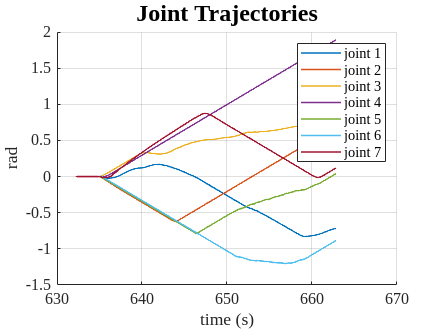

sim_time = joint_state(1,:);
joint_state = joint_state(2:8,:);

figure;
hold on
plot(sim_time, joint_state);
hold off
title("Joint Trajectories")
xlabel("time (s)")
ylabel("rad")
legend("joint 1", "joint 2", "joint 3", "joint 4", "joint 5", "joint 6", "joint 7")